# Image Stitching

Very basic image stitch of two images using an homography transformation (this time, using matlab ready functions)

## Points selection

Select 4 corresponding points between the images 

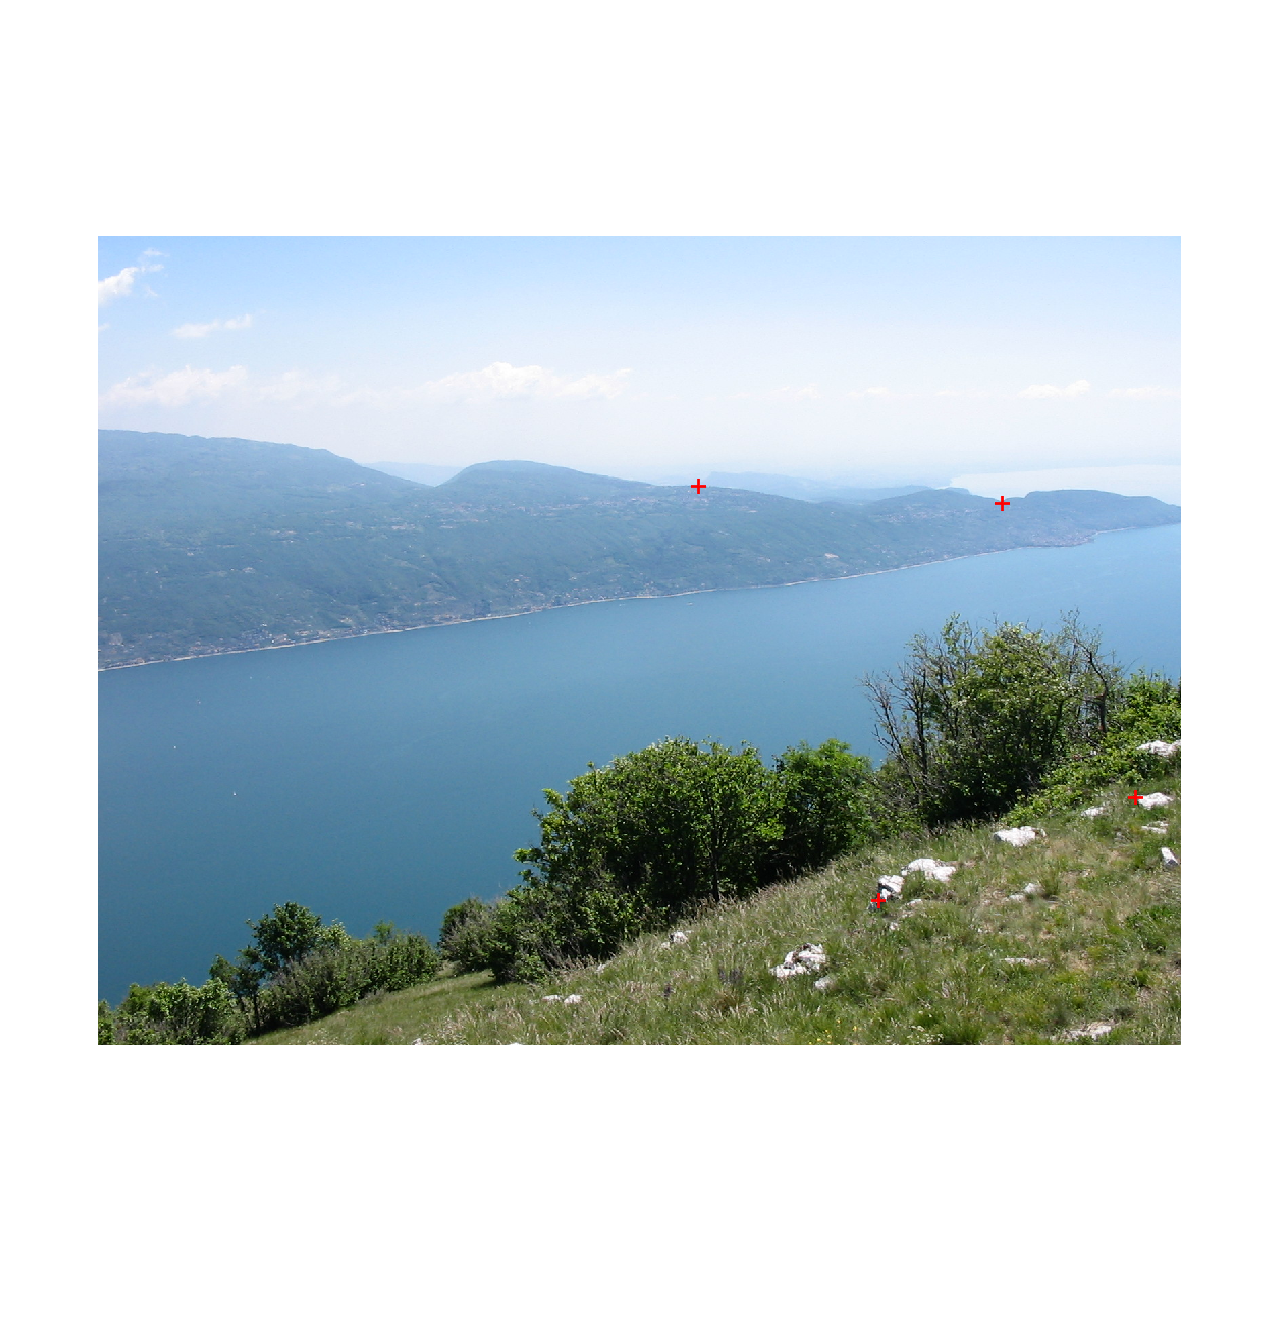

cd ~/Documents/Polimi/IACV/
I1 = imread('images/panorama1.png');
I2 = imread('images/panorama2.png');
fig1 = figure; imshow(I1);
figure(fig1),[x1, y1] = getpts();
figure(fig1), hold on, plot(x1, y1, 'r+', MarkerSize=10, LineWidth=2);
fig2 = figure; imshow(I2);
figure(fig2), hold on, [x2, y2] = getpts();

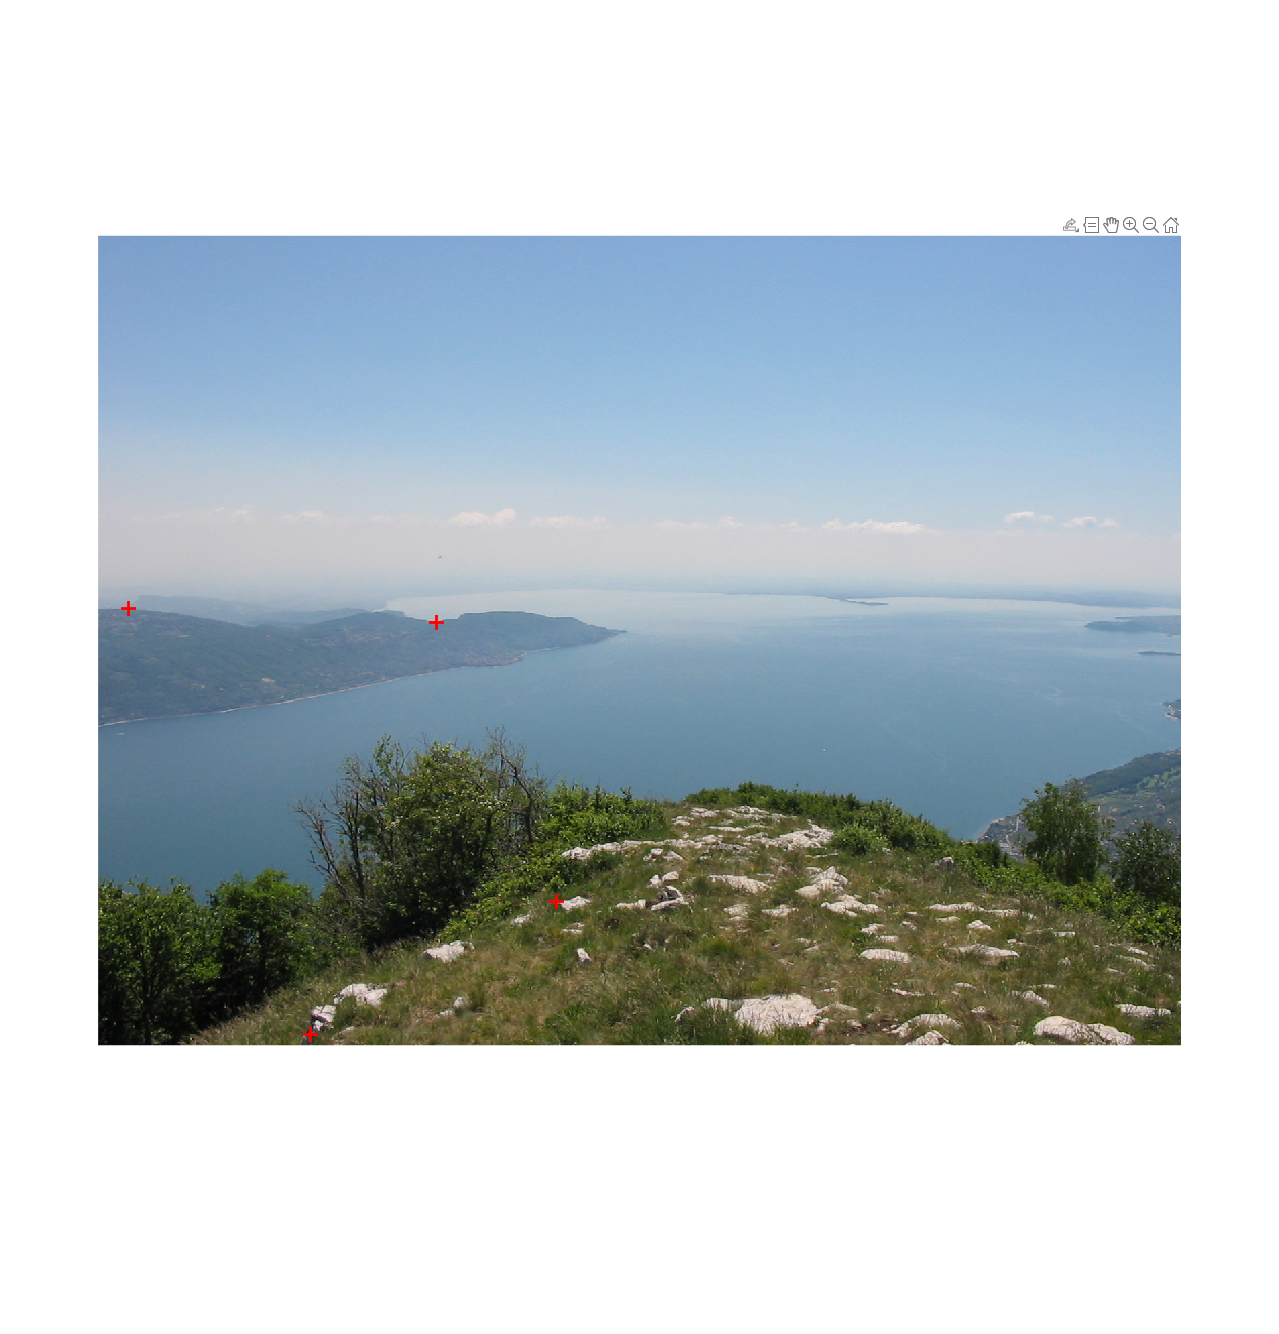

figure(fig2), plot(x2, y2, 'r+', MarkerSize=10, LineWidth=2);

## Homography estimation

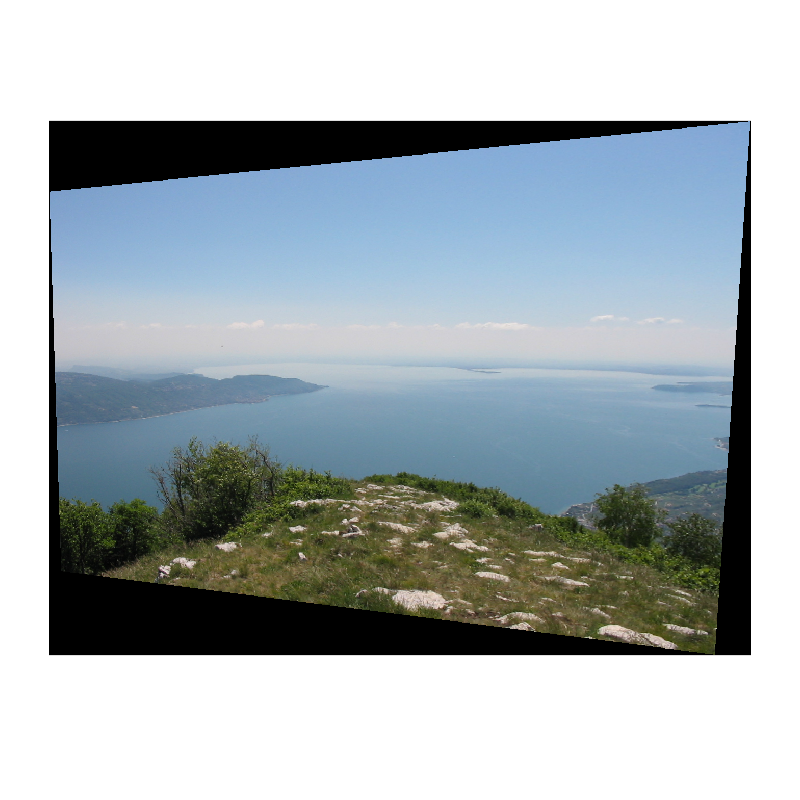

H = fitgeotrans([x2 y2], [x1 y1], 'projective');
I2warp = imwarp(I2, H);
figure(3), imshow(I2warp), axis equal;

## Stitching

We need to apply a displacement to the warped image to overlap them. We can use the average of the difference of the coordinates of the points.

displacement = [x1(1) - x2(1), y1(1) - y2(1)];                                      % the translation of the warped image
imsize = size(I2warp, 1:2) + [displacement(2) displacement(1)];
scale = [(x2(1) - x2(2)) / (x1(1) - x1(2)), (y2(1) - y2(2)) / (y1(1) - y1(2))];     % use the same scale
T = [scale(1) 0 displacement(1); 0 scale(2) displacement(2); 0 0 1]';

outView = imref2d(uint32(imsize));                                                  % the size of the final image
I2Positioned = imwarp(I2warp, affine2d(T), 'OutputView', outView);
I1Positioned = imwarp(I1, affine2d, 'OutputView',outView);

We are going to average the images, but ignoring the non-informative zeros

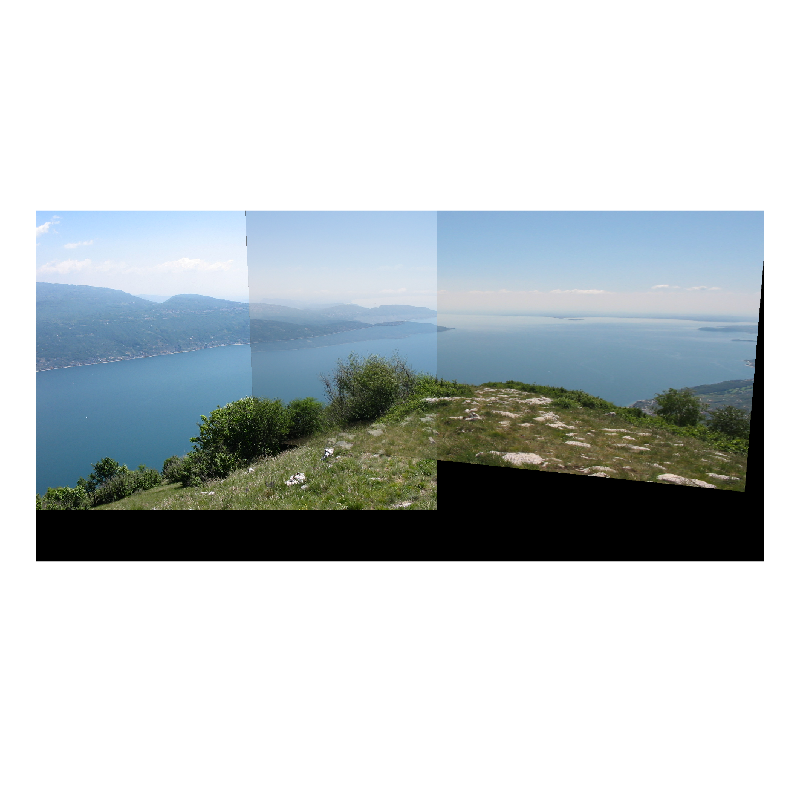

intersectionMask = sum(I1Positioned .* I2Positioned, 3) > 0;
I = (I1Positioned./2 + I2Positioned./2) .* uint8(intersectionMask) + (I1Positioned + I2Positioned) .* uint8(~intersectionMask);                  
figure(4), imshow(I), axis equal;